# pixelgrid

Superimpose a grid of pixel edges on an image

## Description

`pixelgrid` superimposes a grid of pixel edges on the image in the current axes.

`pixelgrid(h_ax)` superimposes the grid on the image in the specified axes.

`pixelgrid(h_im)` superimposes the grid on the specified image.

`group = pixelgrid(_)` returns an hggroup object that contains the two lines that are used to draw the grid. One line is thick and darker, and the other is thin and lighter. Using two contrasting lines in this way guarantees that the grid will be visible regardless of pixel colors.

## Example: Superimpose pixel grid on color image

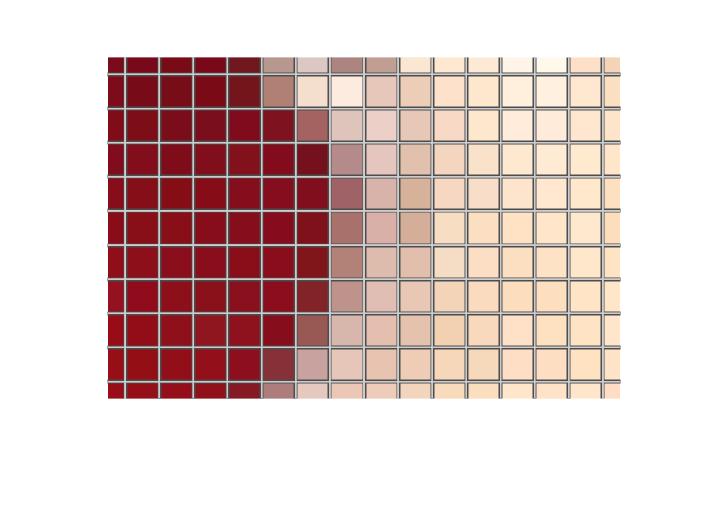

rgb = imread('peppers.png');
imshow(rgb) 
pixelgrid 
axis([440 455 240 250])

## Example: Change the colors and line widths of the pixel grid

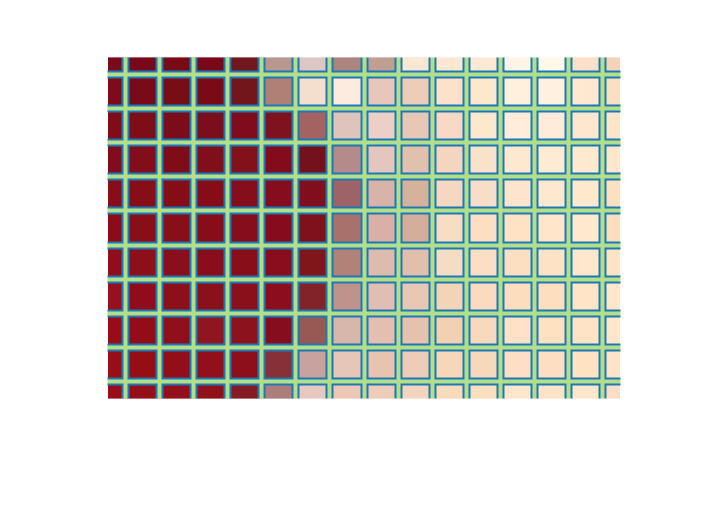

rgb = imread('peppers.png'); 
imshow(rgb) 
h = pixelgrid; 
axis([440 455 240 250]) 
h.Children(1).Color = [178 223 138]/255; 
h.Children(1).LineWidth = 2; 
h.Children(2).Color = [31 120 180]/255; 
h.Children(2).LineWidth = 4;

## Limitations

This function is intended for use when looking at a zoomed-in image region with a relatively small number of rows and columns. If you use this function on a typical, full-size image without zooming in, the image will not be visible under the grid lines.

*Copyright 2017-2019 The MathWorks, Inc.*